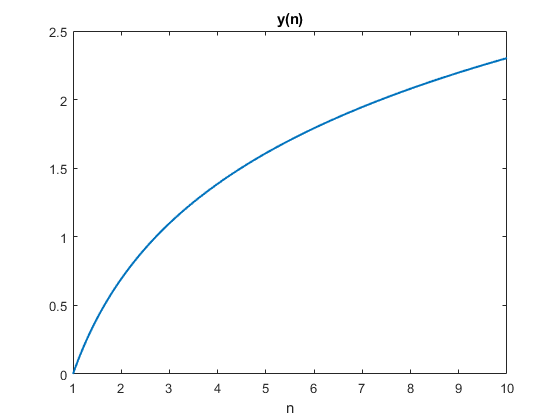

clear
t=1:0.01:10;
data=log(t);
plot(t,data,'LineWidth',1.5);
title('y(n)');
xlabel('n');

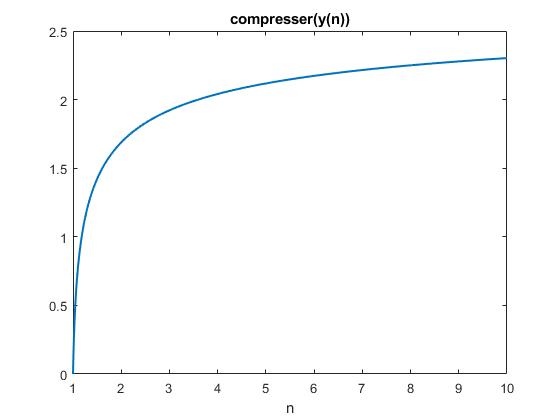

y = compand(data,80,max(data),'mu/compressor');
n=1;m=10;
o=1;
while ( m< length(t))
    
    D=(y(m)+y(n))/2;
    k=round((m+n)/2);
    N=y(k);
    f=N/D;
    if f >1
    nn=m;
    mn=m+round(1.25*(m-n));
    elseif f==1
        nn=m;
        mn=m+m-n
    elseif f<1
        nn=m;
        mn=m+round(0.5*(m-n));
    end
    n=nn;
    m=mn;
    ind(o)=n;
    o=o+1;
end
plot(t,y,'LineWidth',1.5)
title('compresser(y(n))');
xlabel('n');

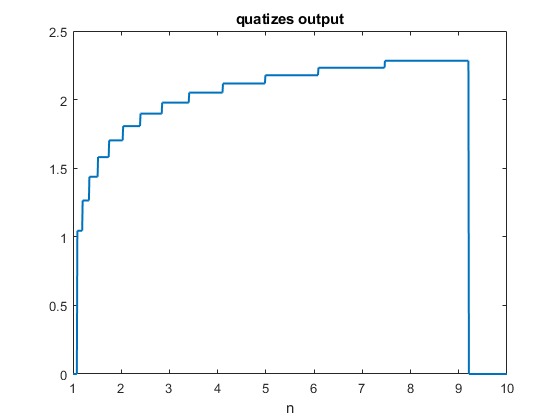

O=zeros(size(y));
for i=1:length(ind)-1
O(ind(i):ind(i+1))=y(ind(i+1));    
end
plot(t,O,'LineWidth',1.5);
title('quatizes output');
xlabel('n');

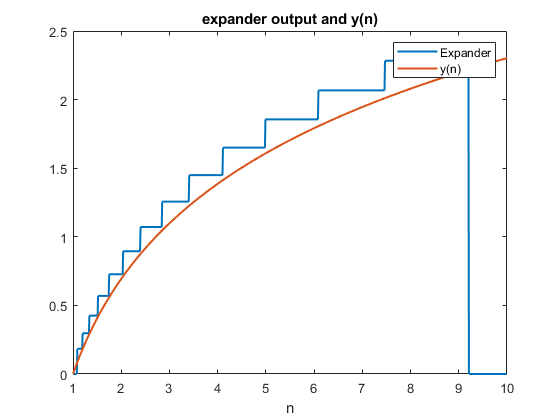

ny= compand(O,80,max(O),'mu/expander');
plot(t,ny,'LineWidth',1.5)
hold on
plot(t,data,'LineWidth',1.5);
title('expander output and y(n)');
xlabel('n');
legend('Expander','y(n)');